# **Copilot for Learners**

[⇦ Main Menu](matlab:open('MainMenu.mlx'))

In this script, we will explore using MATLAB Copilot as a learning partner to guide students in understanding engineering theory and solving associated engineering problems.

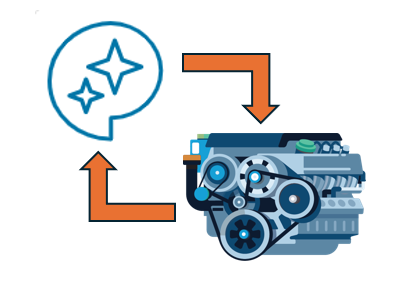

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View** tab of the MATLAB toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code** using the icon   at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2 hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## Introduction

In the [previous script](matlab:open('.\IntroToCopilot.mlx')), an introduction to using GenAI in MATLAB was provided, primarily through the use of MATLAB Copilot. We will take a deeper dive into using MATLAB Copilot by walking through solving some engineering problems from start to finish. Consider Copilot as a consultant to help firm up a solution. Copilot will aid in understanding concepts as we move along in the problem solving process. There will be a number of scenarios presented for working through different engineering domain problems. Some problems will provide information to start from and others will start from the very beginning. 

This will be particularly helpful if you are unfamiliar with the domain in which you are working with. The goal is not for generative AI to replace good engineering, but rather help stimulate a more robust problem solving process in finding an optimal solution.

Recalling from the previous script, the LLM that MATLAB Copilot currently uses is the GPT-5 mini model. This model may change as updates come along. Also recall that LLMs are [stochastic](matlab:open('./GenAIFundamentals.mlx')), so what you see presented in this script will be different from your experience.

 **Warning**. The responses provided herein from MATLAB Copilot are to be looked at as examples for understanding different approaches for solving engineering problems. The responses provided are not an exhaustive list of what Copilot can provide. 

## Prompting

As we have observed using GenAI, one of the most important skills to have is knowledge of [prompting](matlab:open('./GenAIFundamentals.mlx')). In the context of engineering learning, it is less about attempting to tell an AI agent **what** to do, and more about learning how to ask the AI agent **how** to do. **We want to use Copilot as a learning assistant**. Therefore, the prompts that are used can greatly impact the information that you receive. Take for example the following problem and prompts:

###  **Demonstration: **Combustion (Chemistry)

You want to learn about the combustion process in chemistry. Observe the responses from the following prompts.

**Prompt A:**

**Copilot responded with the following:**

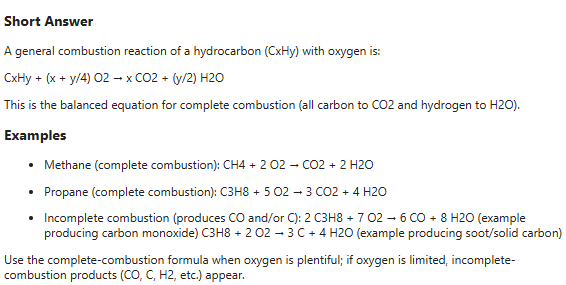

**Prompt B:**

**Copilot responded with the following:**

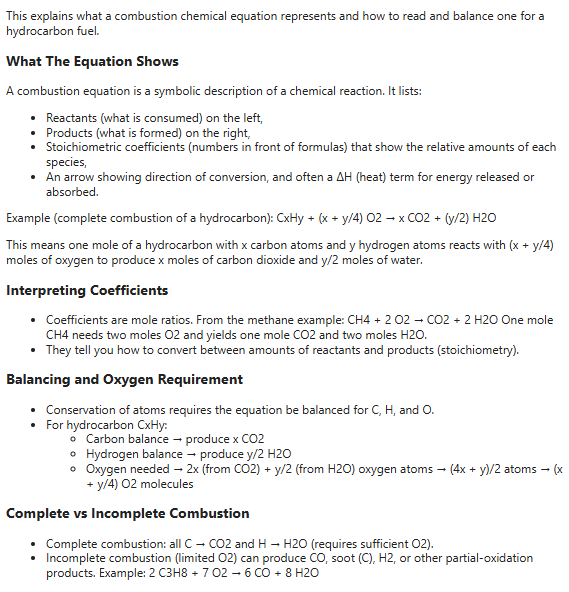

See the difference? From this step, you can dig deeper into specific areas to continue understanding concepts. In some cases, you may need to try more than one prompt as certain entries may cause Copilot to return a message like this:

## **Example 1: Manufacturing (Probability)**

You are an engineering consultant that helps to solve problems for companies. A small manufacturing company has hired you to help them with a recent issue in their product line.

This manufacturing company makes a critical part for a major car manufacturer. The part that is made is mass-produced and two thousand parts are shipped out on a monthly basis. Recently, the cars that have installed this part have found defects in its design, creating in-service safety problems for those operating the cars. It has been discovered that the manufacturing company does not have a great quality control system, allowing parts with defects to make it to shipment. There are a few uncertain elements in this process, complicating the scenario:

- The part defect rate varies from month to month

- The percentage of parts being inspected is 100%

- The probability of identifying a defective part during inspection is around 50-60%

 **Exercise 1. **What do we know so far about this complex probability problem? Please select one option and click the **Submit Answer** button below.

ExerciseSol1(...
    A = false, ...
    B = false, ...
    C = false, ...
    D = false, ...
    E = false, ...
    F = false);
 

 **Application. **You are being tasked with coming up with a system to help catch the defective parts and sort them out from the good parts. Use a **Monte Carlo analysis** to find how many defective parts are accumulated over the course of a month.

### Solution Analysis

Let's begin with a knowledge gathering prompt to figure out how to solve this problem:

**Copilot responded with the following:**

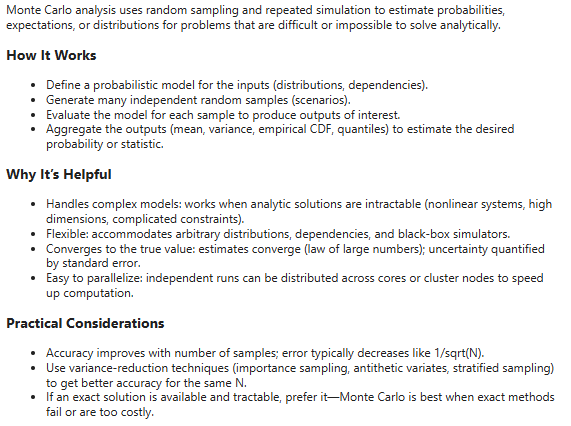

**Copilot also provided some sample code of a simple Monte Carlo to work with:**

Now that we have a better understanding on what Monte Carlo is, we can use Copilot to give us other details that we need to understand. Once we are comfortable with the knowledge gained, we can move on to solving the problem. Let's give Copilot the details of our problem and see how it applies it for Monte Carlo analysis.

**Copilot response:**

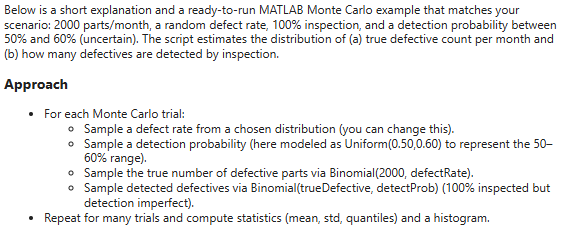

Relevant code was produced from this response that can be run using the button interaction below. You can view the contents of the code [here](matlab:open('..\Data\MonteCarloCode.mlx')).

 
% Check if project is open. If not, add folders to path.
try
    % Run MATLAB script for Monte Carlo analysis
    run MonteCarloCode.mlx;
catch ME
    curloc = matlab.desktop.editor.getActiveFilename;
    rootdir = extractBefore(curloc,filesep+"Scripts");
    addpath(genpath(rootdir));
    run MonteCarloCode.mlx;
end

### **Solution Review**

From the results, it is estimated that the manufacturing company will detect about 22 defective parts per month. In reality, that number is about 40 defective parts based on a 50-60% catch rate. While 40 parts is a low number in comparison to 2000 parts, the issue that remains is it causes safety concerns in-service. With no changes made to the current manufacturing process, the manufacturing company can understand how many parts they have that are defective. This allows for investigation on why they are failing and implement process improvements to fix these issues and improve the number of good parts compared to defective parts.

## **Example 2: Circuit Theory (Electrical)**

You are a relatively new employee at an engineering company, working as chemical engineer. Over the course of a year, you have completed a few projects that are within your skill set. Recently, your supervisor has asked you to work on a new project that involves electrical circuits. This new project requires you to develop an advanced sensor that measures multiple physical properties (temperature, humidity, etc.) at once. The sensor's circuit design is meant to be **closed-loop**. The specification of the circuit is shown below:

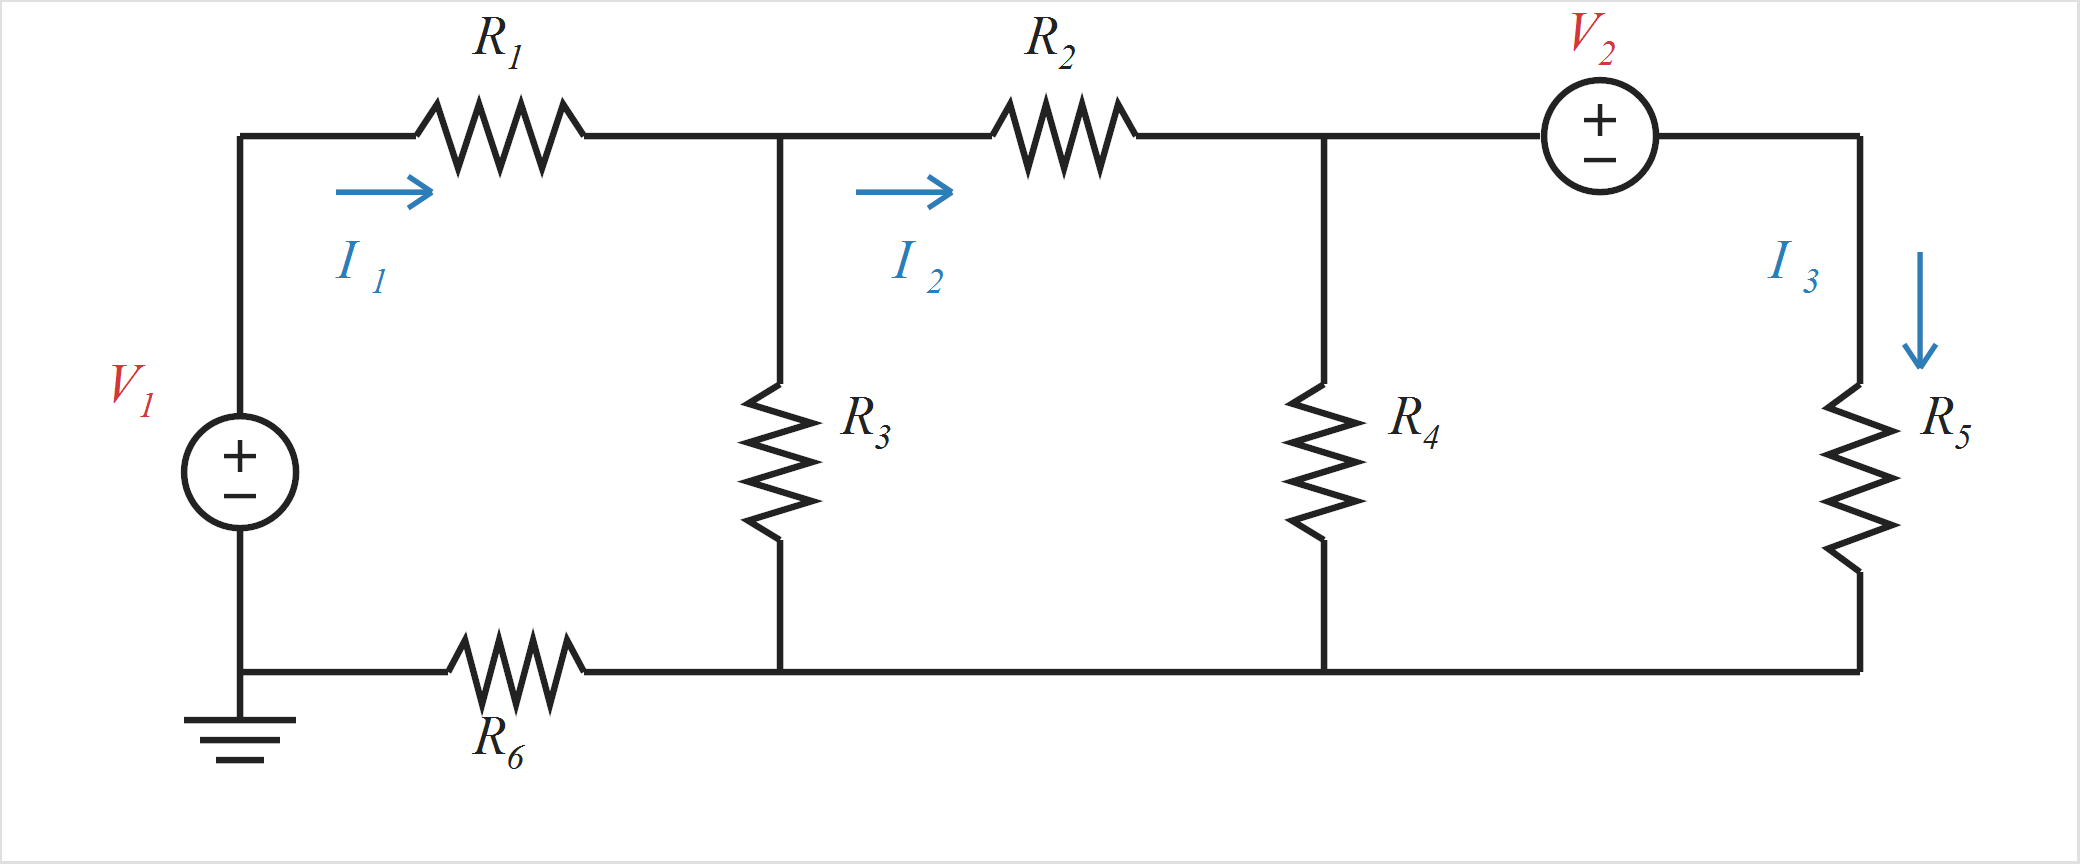

The circuit is defined by the following resistance (Ohms, $\Omega
$) and voltage (Volts, $V$) parameters:

- 
$$R_1 = 100 \ \Omega, R_2 = 10 \ \Omega, R_3 = 220 \ \Omega, R_4 = 1 \ \Omega, R_5 = 200 \ \Omega, R_6 = 1000 \ \Omega$$


- 
$$V_1 = 12 \ V, V_2 = 3 \ V$$


 **Application. **Identify the different currents (Amperes, $A$) required to power different parts of the sensor.

-  
$$[I_1, I_2, I_3] = ?
$$
 

### Solution Analysis

This problem has given us a little less to work off of than the previous one. This is also a domain that you (as the chemical engineer) are unfamiliar with (no skill set).

 **Exercise 2. **What would be a good prompt to start with given what you know so far? Please select one option and click the **Submit Answer** button below.

ExerciseSol2(...
    A = false, ...
    B = false, ...
    C = false, ...
    D = false);
 

**Let's have a conversation with Copilot using the correct prompt from exercise 2:**

 **Note**. Copilot's output has been truncated for space and ease of following a conversational flow. The content shown reflects actual prompts and partial responses: 

 

% Copilot conversation about circuits
disp(' ')
fprintf('Prompt: How do you find three different currents in a closed loop electrical circuit?');
pause(2)
fprintf(['\t\t\t\tResponse: Use circuit-analysis methods (mesh or nodal/KCL with Ohm''s law) and solve the resulting linear equations.\n\t\t\t\t\t  ' ...
        'For a planar circuit with three loops, the standard approach is mesh (loop) analysis: assign three mesh currents,' ...
        '\n\t\t\t\t\t  write KVL for each loop, assemble a 3×3 linear system, and solve for the three unknown currents.']);
pause(3)
fprintf('Prompt: What is mesh analysis and KVL?');
pause(2)
fprintf(['\t\t\t\tResponse: Mesh analysis and Kirchhoff''s Voltage Law (KVL) are basic circuit-analysis tools for finding currents and voltages\n\t\t\t\t\t ' ...
        ' in electrical networks. '...
        ' \n\t\t\t\t\t  Below is a concise explanation of each and how they connect.\n\t\t\t\t\t\t 1. Kirchhoff''s Voltage Law\n\t\t\t\t\t\t\t - Statement: The algebraic sum' ...
        ' of all voltages around any closed loop equals zero.\n\t\t\t\t\t\t 2. Mesh Analysis (Loop Analysis)\n\t\t\t\t\t\t\t - Purpose: Systematically apply KVL to find ' ...
        'unknown currents in a planar circuit by assigning one\n\t\t\t\t\t\t\t ' ...
        '  mesh (loop) current to each independent face of the circuit.']);
pause(3)
fprintf('Prompt: Can you provide an example of applying mesh analysis to a closed circuit with three loops?');
pause(2)
fprintf(['\t\t\t\tResponse: Here''s a complete, concise example that walks through mesh analysis for a planar circuit with three meshes,\n\t\t\t\t\t' ...
         '  including the KVL equations, the 3×3 system, and a MATLAB snippet to solve for the three mesh currents.\n\t\t\t\t\t\t 1. Write KVL for Each Mesh (clockwise around the loop)\n\t\t\t\t\t\t\t' ...
         '- Mesh 1: V1 − R1i1 − R12(i1 − i2) = 0\n\t\t\t\t\t\t\t- Mesh 2: −R12*(i2 − i1) − R2i2 − R23(i2 − i3) = 0\n\t\t\t\t\t\t\t- Mesh 3: V3 − R3i3 − R23(i3 − i2) = 0'])
pause(3)
fprintf(['Prompt: Can you provide an example that describes my circuit? V1 = 12 is on mesh 1. V2 = 3 is on mesh 3.\n\t' ...
        'R1 = 100 and R6 = 1000 are on mesh 1. R2 = 10 is on mesh 2. R3 = 220 is shared between mesh 1 and 2.\n\t' ...
        'R4 = 1 is shared between mesh 2 and 3. R5 = 200 is on mesh 3.']);
pause(3)
fprintf(['\t\t\t\tResponse: Below is a worked mesh-analysis example for your circuit (three meshes). I give the KVL equations, the\n\t\t\t\t\t ' ...
         ' 3×3 matrix, the numeric solution, and the branch currents.' ...
         '\n\t\t\t\t\t\t 1. KVL Equations (V = I*R per mesh)\n\t\t\t\t\t\t\t- Mesh 1: 12 − R1i1 − R6i1 − R3*(i1 − i2) = 0\n\t\t\t\t\t\t\t- Mesh 2: −R3*(i2 − i1) − R2i2 − R4(i2 − i3) = 0' ...
         '\n\t\t\t\t\t\t\t- Mesh 3: 3 − R5i3 − R4(i3 − i2) = 0\n\t\t\t\t\t\t 2. Resistance Coefficient Matrix\n\t\t\t\t\t\t\t- R11 = R1 + R6 + R3 = 100 + 1000 + 220 = 1320' ...
         '\n\t\t\t\t\t\t\t- R22 = R2 + R3 + R4 = 10 + 220 + 1 = 231\n\t\t\t\t\t\t\t- R33 = R5 + R4 = 200 + 1 = 201\n\t\t\t\t\t\t\t- Off-diagonals: R12 = R21 = −220, R23 = R32 = −1, R13 = R31 = 0'])
pause(1)
fprintf('\n\t\t\t\t\t\t 3. Numeric Solution (MATLAB)')
codeText = evalc('type CircuitCode.mlx');
indent = sprintf('\t\t\t\t\t\t\t');
codeText = strrep(codeText, newline, [newline indent]);
fprintf('\n%s%s', indent, codeText);

Now that we have worked from the theory to some sample code, we can view the results for current using the button interaction below. You can view the contents of the code [here](matlab:open('..\Data\CircuitCode.mlx')).

 

% Run MATLAB script for mesh analysis
run CircuitCode.mlx;

### **Solution Review**

From the results, the current values are relatively low (amperes), representing values for current flows inside of a typical measurement sensor. Even if the correct solution was not provided by Copilot, you now have a new information to ask the better questions and learn the process for developing the sensor. Coming from a chemical engineering background, the advantage is gaining the electrical engineering knowledge needed to solve the problem, bringing you closer to finding the exact answer.

While a truncated version of the Copilot conversation was used to provide context on how specific prompts could be structured, it is still possible to go deeper at each step of the conversation. For instance, if Ohm's law is new to you, it would be good to ask Copilot about it before you move forward. The best way to validate this solution is to solve the problem by hand and see how close it is to what was provided by Copilot. Now that you have some basics concepts, the idea is to take that knowledge and learn how to properly execute a mesh (loop) analysis for an electrical circuit.

## **Example 3:  Heart Rate Monitoring (Signal Processing)**

As an exercise enthusiast, you have wearable technology that helps to track your vitals when you are exercising. Heart rate (measured in beats per minute) is a key indicator during exercise, helping you monitor training intensity, achieve fitness goals, and assess overall cardiovascular health. The wearable allows you to export the data for further analysis on a computer. However, when reviewing the heart rate measurements, you notice that the data is highly erratic and difficult to interpret. To better understand your exercise performance and health trends, you need a method to smooth the data while preserving its overall pattern. You can view the heart rate measurements and  using the following button:

 **Note**. The following plots are based simulated data points, not real measured data. To view the code, click [here](matlab:open('..\Data\HeartRateCode.mlx')).

 

 % Run MATLAB script for heart rate monitoring
 run HeartRateCode.mlx;

 **Application. **Analyze the frequency range containing the underlying heart-rate trend using a Fast Fourier Transform (FFT). Then, design a filter that smoothes the noise while preserving the original signal behavior.

### Solution Analysis 

  **Try**. Using Copilot, we can get learn about and perform signal processing for this heart rate data. Enter the following prompts separately in Copilot Chat. After exploring each of its responses, return to this script:

  **Pro-tip**. To view the FFT results from Copilot Chat, you can run the code directly in the MATLAB Command Window using the following buttons in Chat:  

So what did we gather from Copilot's responses to the prompts above?

- An FFT converts a signal from time to frequency domain

- Filter designs are computationally easier in the frequency domain

- Based on FFT output, you can decide to keep/remove frequencies you don't want to support filter design

- When you provide your data to Copilot Chat, it can create FFT code that is ready to run on your dataset

Based on the results from Copilot Chat, your FFT of the heart rate data should look similar to this:

 

 %% Run FFT for heart rate monitoring
 plotFFT(heartRate);

 **Reflect**. Why do the FFT plot from Copilot and the FFT plot above not match? Hint: Review the heart rate measurement [code](matlab:open('..\Data\HeartRateCode.mlx')).

Let's proceed to designing a filter to remove some of the noise. Try the following prompt in Copilot. After exploring the response, return to this script:

 **Exercise 3. **From Copilot's response, which of the following is a valid step in designing a filter for signal? Please select one option and click the **Submit Answer** button below.

 ExerciseSol3(...
     A = false, ...
     B = false, ...
     C = false, ...
     D = false);
  

  **Try**. Now that you have an idea of how to design a filter, use Copilot to develop your filter code for the `heartRate` data. Run your solution in the MATLAB Command Window and analyze the result.

Here is the solution that was created for this problem. How does it match up with what Copilot provided?

 

 %% Run filter for heart rate monitoring
 plotFilter(heartRate);

In the process of making this solution with Copilot, it provided code that turned out to produce an error:

fprintf(2,'Error in Function filtfilt: Data length must be greater than 357, which is the maximum between three times the filter order 119 and 1.\n')

After providing this error back to Copilot, it provided the reason behind the error and improved the code. The plot above is from the improved code. Here was Copilot's response:

 fprintf("filtfilt enforces that the data length > 3 * filterOrder (actually > 3max(length(a),length(b))). \nYour FIR order (120) requires at least 361 samples (3120 + 1), but your signal has 300 samples, so filtfilt throws that error. \nYou can fix this by lowering the FIR order, using a causal filter, or temporarily padding the data before calling filtfilt. \nBelow are three safe fixes with code you can drop into your script.")

Beyond this error, there were a few more issues in getting the code to work and achieve the filtering goal. The takeaway here is that you should continue asking questions to Copilot until you have a clear understanding of its output (and the filter design process!).

### **Solution Review**

Given the help from Copilot, a simple FIR filter was applied to the original simulated heart rate signal. The filter was based on the FFT response of the heart rate signal. In the frequency domain, it was observed that the stable area of the signal that we wanted to keep was between 0.5 - 4 Hz, also known as the passband, which means everything else was filtered out. While this has filtered out some of the unwanted frequencies, it still has not smoothed out the signal like we originally wanted. We still have some noisy peaks and sharp transitions between heart rates.

 **Reflect**. Given the FIR filtered signal, what would be your next approach to getting a smoother heart rate signal?

## **Example 4: Prototyping (Mechanical)**

A vehicle manufacturer wants to improve ride comfort while maintaining tire contact with the road. As an automotive engineer, your goal is to determine the best type of suspension worth pursuing. There is a need to strike a balance between cost and performance. To determine the best option, the plan is to prototype a model of the suspension and test out different stiffness and damping parameters.

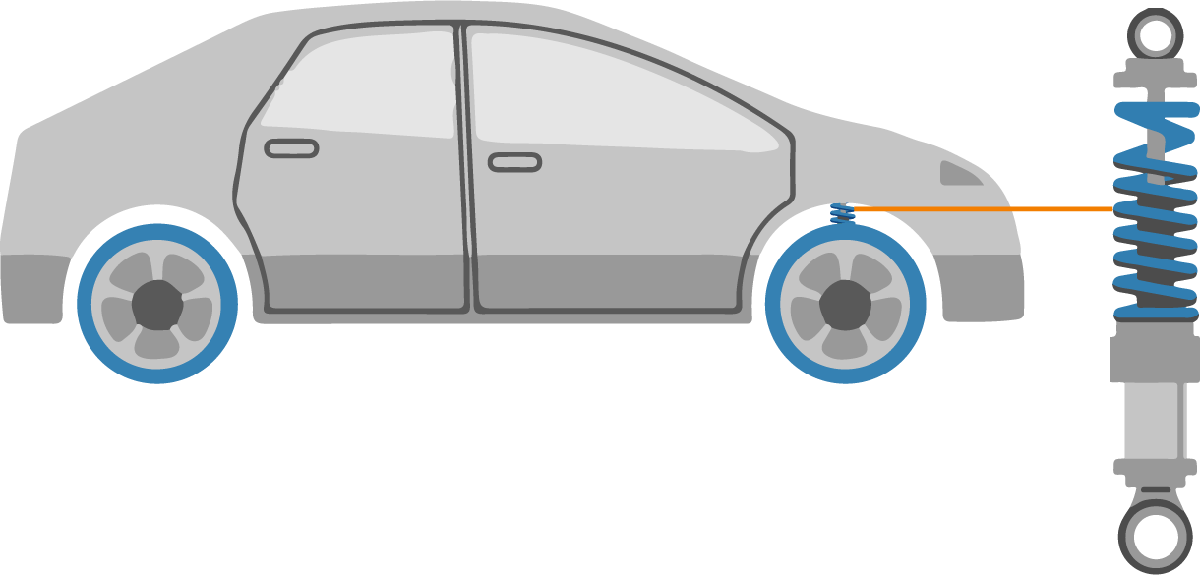

There are a couple requirements to keep in mind for this suspension design:

- Body displacement shall remain within ±5 cm.

- Settling time shall be less than 3 s.

 **Application. **Build a **quarter-car model** of a suspension system that meets the aforementioned requirements. Use Simscape and Simulink Copilot for the development.

 **Pro-tip**. Due to the current [limitations](https://www.mathworks.com/help/releases/R2026a/simulink-copilot/ug/explain-models-and-errors-using-simulink-copilot.html#mw_3eb93138-7c54-4173-868c-3e5b16c97d73) of Simulink Copilot, there is no automatic creation of models. However, you can use Copilot to provide insights and answer questions about how to develop the model.

### Solution Analysis

  **Try**. To begin, let's open a blank Simulink model. You will go back and forth between the model and Copilot as you build.

 

name = new_system;      % create a new blank model (returns name)
open_system(name);      % open the model in the Simulink editor

Then, open Simulink Copilot Chat using the button in the toolstrip. Because we are trying to prototype, let's try out some prompts in Simulink Copilot:

From the response, we can understand that this is a model that is characterized by a mass-spring-damper system. The quarter-car model has two masses, two springs, two dampers, and a road input for displacement. We will need to add those blocks to our model. Try the following prompt in Copilot:

Now that we have the core of the model assembled, we still need a few pieces to make this system run as we want so that we can test different stiffness and damping combinations. Next try this prompt:

This is a sample of what the model could look like. Depending on how the construction was approached using Copilot, your model may look different. The key is ensuring the mass-spring-damper model is built correctly and the inputs are setup to test for the requirements.

 

% Open quarter-car model
open_system("QuarterCarSuspension.slx"); 

We can use this model moving forward for consistency. One thing to keep in mind is that the values of the quarter-car are the default values and may not be representative of the vehicle. Let's add some sample parameters for these blocks. You can run the following code in the Command Window to update the model:

Run the model with these parameters and open the scope block (in green) to view the displacement of the body and the tire.

 **Pro-tip**. To verify that this code changed the block values, open up each block mask to view the parameters to ensure that they match.

 **Reflect**. Think back to the problem's requirements. What do you observe about the results in the scope block? 

 **Exercise 4. **Based on the **current configuration** of the model, which parameter will have the greatest impact on meeting the requirements? Please select one option and click the **Submit Answer** button below.

ExerciseSol4(...
    A = false, ...
    B = false, ...
    C = false, ...
    D = false);
 

Now, let's test out various suspension stiffness and damping parameters to find the best combination that meets the requirements. It is possible to log the scope data during a model run and have it sent to the MATLAB workspace. We can retrieve the data and plot it in this script. Then, we can vary the parameters interactively. Let's ask Copilot how we can go about logging model data:

After logging the data in the workspace, some code was written to plot it. Use the following button to run the model and plot the data:

 

% Run the model
out = sim("Models\QuarterCarSuspension.slx");

% Time data 
Time = out.logsout{1}.Values.Time;

% Displacement data
BDisp = out.logsout{1}.Values.Data;
TDisp = out.logsout{2}.Values.Data;

% Plot scope data
figure
plot(Time,BDisp,Time,TDisp)
xlabel("Displacement (cm)")
ylabel("Time (secs)")
title("Quarter-Car Model")
legend("bodyDisp","tireDisp")

  **Try**. Use the interactive sliders to change suspension stiffness (ks) and damping (cs) to achieve the problem requirements. The requirements have been noted on the plot using dashed lines.

ks =18000; cs =1500;

% Set model parameters
set_param('QuarterCarSuspension/ks','spr_rate','ks')
set_param('QuarterCarSuspension/cs','D','cs')

% Run the model
out = sim("Models\QuarterCarSuspension.slx");

% Time data 
Time = out.logsout{1}.Values.Time;

% Displacement data
BDisp = out.logsout{1}.Values.Data;
TDisp = out.logsout{2}.Values.Data;

% Create requirements bounds for plot
req1 = ones(numel(Time),1)*5;
req2 = ones(numel(Time),1)*3;
BPad = zeros(numel(req2),1); %#ok<PREALL>
BPad = linspace(0,max(BDisp)+1,numel(req2));

% Plot scope data with requirements bounds
figure
plot(Time,BDisp,Time,TDisp)
hold on
plot(Time,req1,"LineStyle","--","SeriesIndex",5)
plot(req2,BPad,"LineStyle","--","SeriesIndex",4)
hold off
xlabel("Time (secs)")
ylabel("Displacement (cm)")
ylim([0 max(BDisp)+1])
title("Quarter-Car Model")
legend("bodyDisp","tireDisp","5cm Req","3s Req")

### **Solution Review**

By using the requirement lines in the plot as a boundary, the best combination for suspension stiffness and damping can be found. If the sliders were adjusted to the correct value range, it can be observed that the your body displacement (blue line) should be under 5 cm on the Y-axis, and the settling time of the blue line should have been less than 3 seconds on the X-axis. Based on these results, the model shows that the original problem's requirements were met. Explanations and details from Copilot helped to build this model. From that information, we were able to transform a blank canvas into a modifiable test bench for a vehicle's suspension system.

Upon completion of the previous activities, let's clean up our working environment:

  

 % Check if project is open. If not, remove folders to path.
 if isempty(matlab.project.rootProject) == 0
     ...
 else
     curloc = matlab.desktop.editor.getActiveFilename;
     rootdir = extractBefore(curloc,filesep+"Scripts");
     rmpath(genpath(rootdir));
 end

## Next Steps

In this module, we have seen how MATLAB interacts with LLMs and AI Chatbots to help solve engineering problems. This is an involved process by the user going back and forth, continuously refining prompts. Rather than performing one action at a time, what if you could assign a plan and goal to an AI tool and then review the work it creates to ensure it meets your needs? Agentic AI is a natural progression from working with LLMs or AI Chatbots. It is where one or more AI Agents autonomously plan, coordinate, and carry out complex multi-step tasks and workflows end-to-end. You can explore more about Agentic AI in the Further Exploration section.

## Further Exploration

- [MATLAB and Simulink Agentic Toolkit + MCP](https://github.com/matlab/simulink-agentic-toolkit)

- [Minimal MATLAB Agent with Ollama](https://github.com/toshiakit/minimal-matlab-agent)

[⇦ Return to the main menu](matlab:open('MainMenu.mlx'))

## Local Helper Functions

If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

function ExerciseSol1(options)
    % Provides feedback for Exercise 1
    arguments
        options.A (1,1) logical
        options.B (1,1) logical
        options.C (1,1) logical
        options.D (1,1) logical
        options.E (1,1) logical
        options.F (1,1) logical
    end

    if ~any([options.A options.B options.C options.D options.E options.F])
        disp("Please select all that apply!")
    elseif options.A && ~any([options.B options.C options.D options.E options.F])
        warning("Yes, only two types of parts have been identified. However, is this all the information we know? Please revisit the problem statement.")
    elseif options.B && ~any([options.A options.C options.D options.E options.F])
        warning("The defect rate was mentioned to be random. However, is this all the information we know? Please revisit the problem statement.")
    elseif options.C && ~any([options.A options.B options.D options.E options.F])
        warning("Yes, two thousand parts ship per month. However, is this all the information we know? Please revisit the problem statement.")
    elseif options.D && ~any([options.A options.B options.C options.E options.F])
        warning("It was stated that there are safety issues with the part. However, is this all the information we know? Please revisit the problem statement.")
    elseif options.E && ~any([options.A options.B options.C options.D options.F])
        disp("Correct! All of the choices contain information that has been provided in the probability problem.")
    elseif options.F && ~any([options.A options.B options.C options.D options.E])
        warning("Incorrect. There is information provided here that qualifies as knowledge of the probability problem.")
    else % Any other combination
        warning("You selected too many options. Please go back and choose one answer.")
    end
end

function ExerciseSol2(choices)
    % Provides solution for Exercise 2
    arguments
        choices.A (1,1) logical
        choices.B (1,1) logical
        choices.C (1,1) logical
        choices.D (1,1) logical
    end
    
    if ~any([choices.A choices.B choices.C choices.D])
        disp("Please select all that apply!")
    elseif choices.A && ~any([choices.B choices.C choices.D])
        warning("Incorrect. This prompt is too general to be helpful in solving this problem.")
    elseif choices.B && ~any([choices.A choices.C choices.D])
        disp("Correct! This is a very specific ask that will help to focus in on a more tailored response.")
    elseif choices.C && ~any([choices.A choices.B choices.D])
        warning("Incorrect. While this prompt may get you started down the path of learning about current, it may not be enough to begin exploring circuit theory.")
    elseif choices.D && ~any([choices.A choices.B choices.C])
        warning("Incorrect. While this may provide more context about how sensors are used in a chemical engineering setting, it would not help you progress in solving this problem.")
    else % Any other combination
        warning("You selected either too many options or an option that do not constitute as a good initial prompt for this problem.")
    end
end

function ExerciseSol3(choices)
    % Provides solution for Exercise 3
    arguments
        choices.A (1,1) logical
        choices.B (1,1) logical
        choices.C (1,1) logical
        choices.D (1,1) logical
    end

    if ~any([choices.A choices.B choices.C choices.D])
        disp("Please select all that apply!")
    elseif choices.A && ~any([choices.B choices.C choices.D])
        disp("Correct! This is crucial to ensuring the specifications of the filter selected are met.")
    elseif choices.B && ~any([choices.A choices.C choices.D])
        warning("Not quite. The focus is to inspect frequencies produced by the FFT, not add more frequencies.")
    elseif choices.C && ~any([choices.A choices.B choices.D])
        warning("Incorrect. Based on what we learned from Copilot, it is recommended to perform inspection in the frequency domain.")
    elseif choices.D && ~any([choices.A choices.B choices.C])
        warning("Somewhat correct, if you have perfomed an FFT already, you do not need to perform a Welch PSD. Try again.")
    else % Any other combination
        warning("You selected either too many options or an option that is not a valid step in filter design.")
    end
end

function ExerciseSol4(choices)
% Provides solution for Exercise 4
    arguments
        choices.A (1,1) logical
        choices.B (1,1) logical
        choices.C (1,1) logical
        choices.D (1,1) logical
    end

    if ~any([choices.A choices.B choices.C choices.D])
        disp("Please select all that apply!")
    elseif choices.A && ~any([choices.B choices.C choices.D])
        disp("Correct! Currently, the plot shows that the settling time is within 3 seconds. It is the body displacement that needs to be brought within range.")
    elseif choices.B && ~any([choices.A choices.C choices.D])
        warning("Incorrect. The tire stiffness has less impact on improving the body displacement.")
    elseif choices.C && ~any([choices.A choices.B choices.D])
        warning("Incorrect. The Suspension stiffness has more impact on the settling time than the body displacement.")
    elseif choices.D && ~any([choices.A choices.B choices.C])
        warning("Incorrect. The tire damping is typically small and has less impact on improving the body displacement.")
    else % Any other combination
        warning("You selected either too many options or an option that is the most impactful parameter.")
    end
end

function plotFFT(heartRate)
    % Plot the FFT of the heart rate signal
    % Time vector
    t = linspace(0,30,300); % minutes
    
    % Sampling Frequency Rate
    dt = mean(diff(t));            % minutes per sample
    Fs = 1/dt;                     % samples per minute (cpm sampling rate)
    
    % Length of Signal
    N = length(heartRate);
    
    % Zero-pad to next power of two for denser frequency grid
    Nfft = 2^nextpow2(N);
    
    % Calculate FFT of Signal
    Y = fft(heartRate,Nfft);
    
    % Single-sided magnitude spectrum
    P2 = abs(Y)/N;
    P1 = P2(1:Nfft/2+1);
    P1(2:end-1) = 2*P1(2:end-1);
    f = Fs*(0:(Nfft/2))/Nfft;
    
    % Plot FFT
    figure
    plot(f,P1,'.-','MarkerSize',8)
    xlabel('Frequency (Hz)')
    ylabel('Magnitude (bpm)')
    title('Exercise Heart Rate FFT')
    grid on
end

function plotFilter(heartRate)
    % Plot filtered response of heart rate signal
    % Time vector
    t = linspace(0,30,300); % minutes
    
    % Sampling Frequency Rate
    dt = mean(diff(t));            % minutes per sample
    Fs = 1/dt;                     % samples per minute (cpm sampling rate)

    % Normalized frequencies (0..1) for fir1 where 1 -> Nyquist (Fs/2)
    nyq = Fs/2;
    fp = [0.3 4];           % passband (cpm)
    Wp = fp/nyq;
    
    % Choose filter order (start with moderate order)
    x = heartRate - mean(heartRate);
    order = 80;            % higher order -> narrower transition, more computation
    b_fir = fir1(order, Wp, 'bandpass', hann(order+1));  % windowed FIR. No 'a' coefficients for FIR (a = 1)
    
    % Apply FIR filter
    y_fir = filtfilt(b_fir, 1, x);
    
    % Add mean after filtering
    y_firN = y_fir + mean(heartRate); 

    % Plot comparison
    figure;
    plot(t, y_firN, '-b', 'DisplayName','FIR filtered');
    xlabel('Time (minutes)'); 
    ylabel('Heart Rate (bpm)');
    legend; 
    grid on; 
    title('Filtered Exercise Heart Rate');
end